load('poly_data.mat')
k = length(sampx);
p = 6;
x0 = ones(p,k);

for i = 1:p-1
    x0(i + 1,:) = sampx .^ i;
end

theta_LS = funLS(x0, sampy);

theta =     0.6158
    1.1041
    1.3302
   -0.6932
    0.0009
   -0.6861


theta_RLS = funRLS(x0, sampy);
theta_LASSO = funLASSO(x0, sampy);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping cr

theta_RR = funRR(x0, sampy);


Optimal solution found.



[var_BR, mean_BR] = funBR(x0, sampy);

for i = 1:p-1
    xn(i + 1,:) = polyx .^ i;
end

y0_LS = xn' * theta_LS;
y0_RLS = xn' * theta_RLS;
y0_LASSO = xn' * theta_LASSO;
y0_RR = xn' * theta_RR;
y0_BR = xn' * mean_BR;
var_fin = xn' * var_BR * xn;

ms_LS = mean((y0_LS - polyy) .^ 2);
ms_RLS = mean((y0_RLS - polyy) .^ 2);
ms_LASSO = mean((y0_LASSO - polyy) .^ 2);
ms_RR = mean((y0_RR - polyy) .^ 2);
ms_BR = mean((y0_BR - polyy) .^ 2);

figure(1);
    disp(ms_LS);

    1.4291



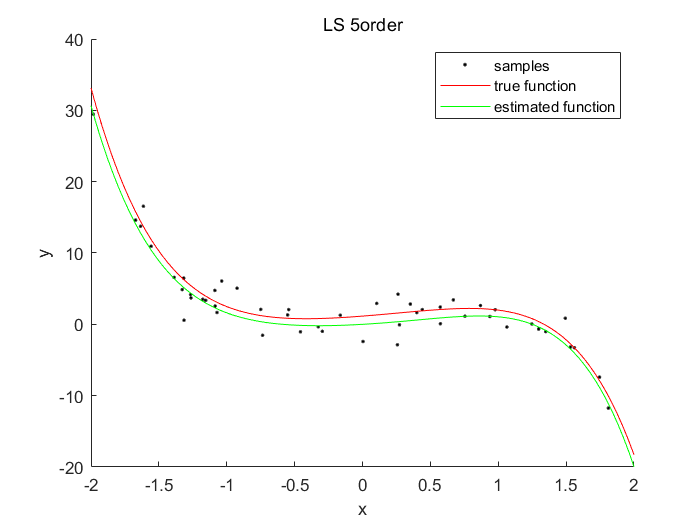

    scatter(sampx,sampy,25,'.','k');
    hold on 
    plot(polyx,polyy,'r');
    hold on
    plot(polyx,y0_LS,'g');
    xlabel('x');
    ylabel('y');
    title('LS 5order');
    legend('samples','true function','estimated function')

figure(2);
    disp(ms_RLS);

    1.5135



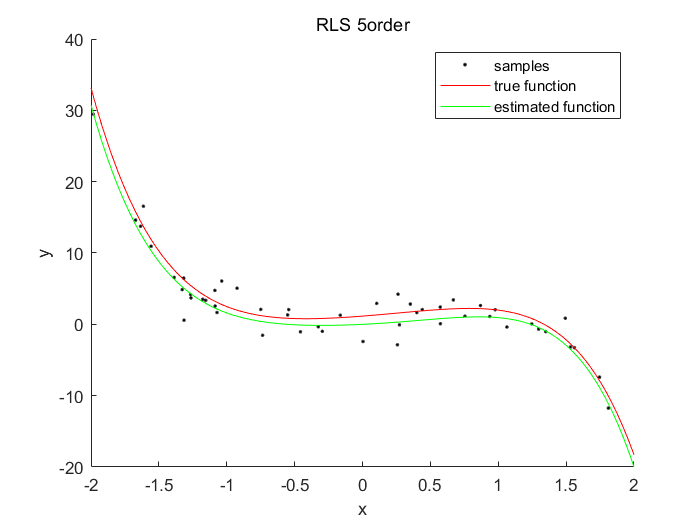

    scatter(sampx,sampy,25,'.','k');
    hold on 
    plot(polyx,polyy,'r');
    hold on
    plot(polyx,y0_RLS,'g');
    xlabel('x');
    ylabel('y');
    title('RLS 5order');
    legend('samples','true function','estimated function')

figure(3);
    disp(ms_LASSO);

    1.4782



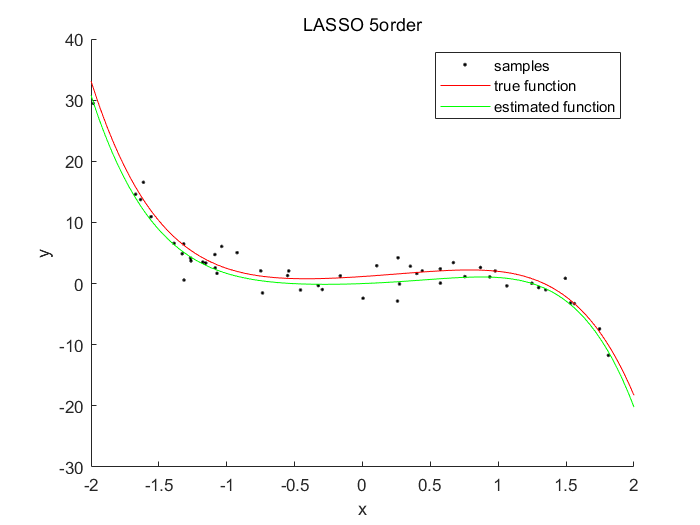

    scatter(sampx,sampy,25,'.','k');
    hold on 
    plot(polyx,polyy,'r');
    hold on
    plot(polyx,y0_LASSO,'g');
    xlabel('x');
    ylabel('y');
    title('LASSO 5order');
    legend('samples','true function','estimated function')

figure(4);
    disp(ms_RR);

    2.6608



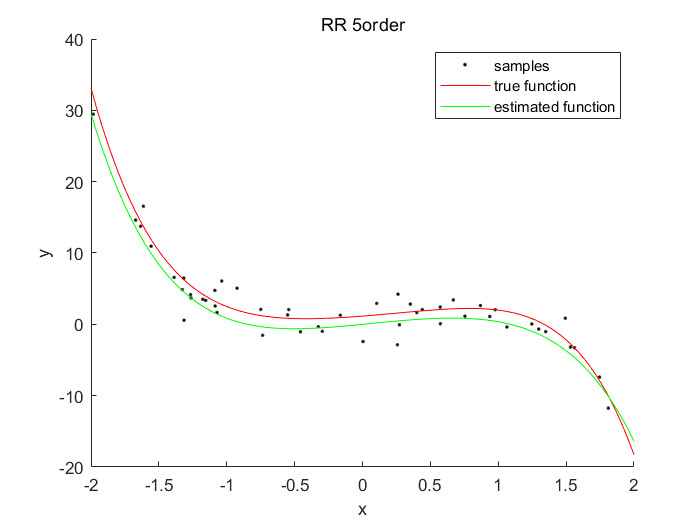

    scatter(sampx,sampy,25,'.','k');
    hold on 
    plot(polyx,polyy,'r');
    hold on
    plot(polyx,y0_RR,'g');
    xlabel('x');
    ylabel('y');
    title('RR 5order');
    legend('samples','true function','estimated function')

figure(5);
    disp(ms_BR);

    1.5796



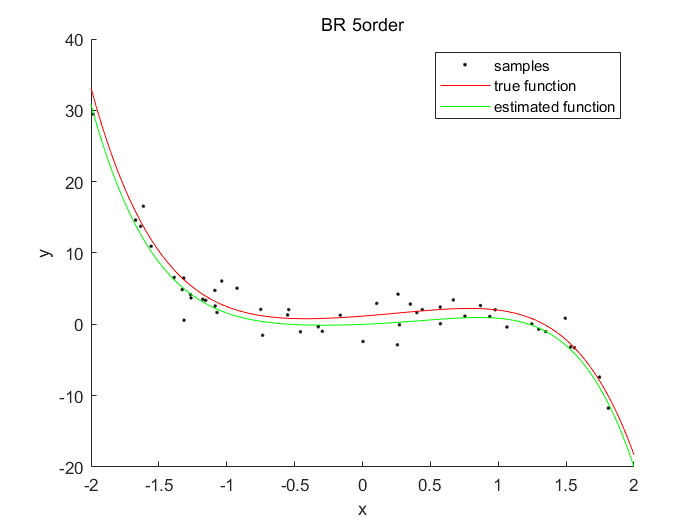

    scatter(sampx,sampy,25,'.','k');
    hold on 
    plot(polyx,polyy,'r');
    hold on
    plot(polyx,y0_BR,'g');
    xlabel('x');
    ylabel('y');
    title('BR 5order');
    legend('samples','true function','estimated function')